# Overview of MATLAB Data Types

Note: Run this live script** section by section**. Each section contains executable code examples. Don't worry if the code looks advanced, you don't need to fully understand it at this point. Use this live script as your resource whenever you want to know something about a data type used later in the course.

Throughout this live script, you will see references to data files which are included with MATLAB. This means that these files get downloaded with MATLAB during the installation process to be used as examples. The files are stored with the installation files, so you won't see them in the Current Folder, but don't worry, MATLAB still can access them.

## MATLAB Data Types

All data scientists work with data. However, the type and format of that data varies. No matter the format, all data is made up of **numbers** and **text**. All data will be assigned a data type once it has been imported into MATLAB, representing either numerical or non-numerical data. A data type is an attribute of data and defines how you are able to use it.

The data types you already worked with are:

- double

- string

- categorical

- datetime

- table

In MATLAB, there are data types for either homogeneous or heterogeneous data. Data is **homogeneous** if it is all of the same type and **heterogeneous** if it contains a vartiety of types. In the picture below you see an overview of **all** available data types. 

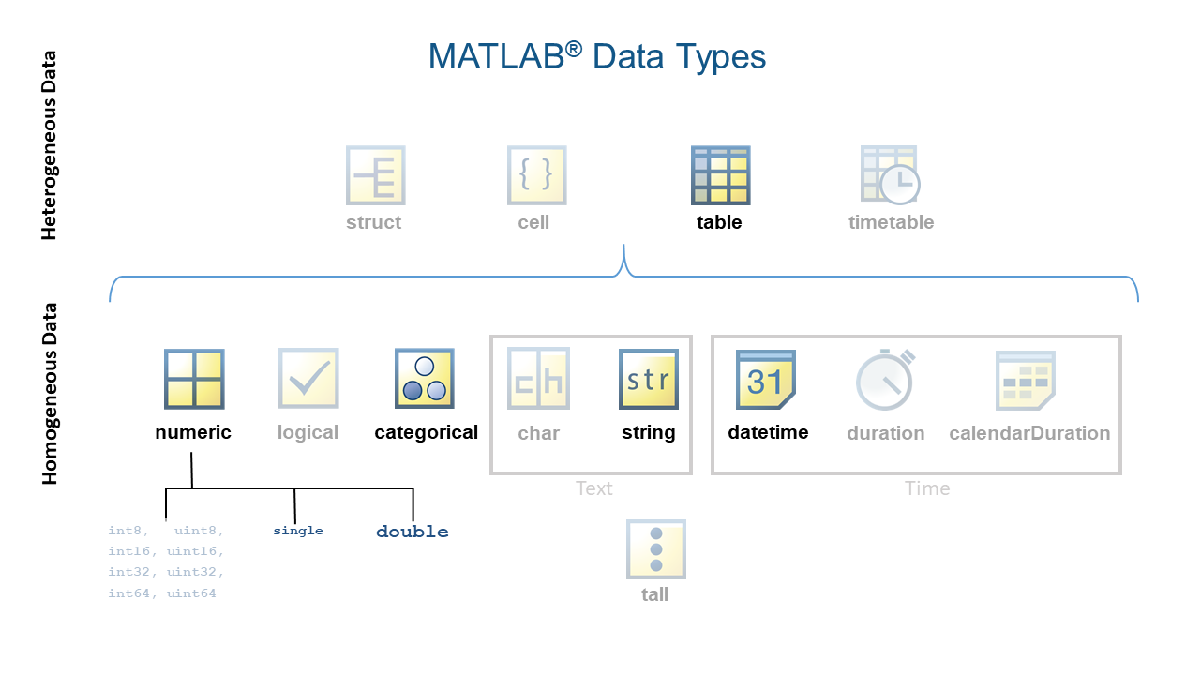

In this course, you will be needing only double, string, categorical, datetime, logical and table. The following sections explore examples for each of the types of data.

## Homogeneous Data

### Numbers

The default data type for numeric data in MATLAB is `double`. You have seen this with the weather dataset in this lesson. Now, create your own variable, containing a number:

myNumber = 11

myNumber = 11

To create a vector with several observations, use square brackets `[]`. Using a comma (or simply a space) as a separator results in a row vector whereas a semicolon  creates a column vector.

myVecRow = [11, 13, 12, 14]

myVecRow =     11    13    12    14


myVecCol = [11; 13; 12; 14]

myVecCol =     11
    13
    12
    14


To access a single element of the vector, use this notation:

myVecCol(2)

ans = 13

The number 2 represents the *index*, or location of the element in the vector `myVecCol`. You'll learn more about vectors and matrices later in the course. 

The name `double` is both the name of the data type and the name of a function. Passing variables of other data types to the double function results in a data type double when a conversion is possible. Consider a `string` variable `aString` which stores the number seven as text. Don't worry, you can read more about strings in this live script.

aString = "7"

aString = "7"

If a number is represented as a `string`, you will not be able to perform the usual artithmetic operations.  However, after converting a `string` variable to a `double`, you can use the resulting variable as you would expect.

aDouble = double(aString)

aDouble = 7

Now, you could do calculations with `aDouble` because you converted it to a number. Try it out yourself:

- Add 2 to the variable `aString` and run the section. 

- Then, try adding 2 to aDouble and run the section again to see the result.

% enter your code here
aString + 2

ans = "72"

aDouble + 2

ans = 9

### **Logical**

The `logical` data type represents `true` or `false` using the numbers `1` and `0`, respectively. Certain MATLAB functions and operators return logical values to indicate fulfillment of a condition. You can use those logical values to index into an array or execute conditional code.

There are several ways to create a logical variable. The following code illustrates two examples:

myLogVar1 = true

myLogVar1 = logical
   1


myLogVar3 = logical([1; 0; 1])

myLogVar3 = 3×1 logical array
   1
   0
   1


Now, create the vector `Damage_Cost`:

damageCost = [100; 20; 0; 75; 80]

damageCost =    100
    20
     0
    75
    80


Then, use the relational operator `>` to identify the places where `damageCost` was larger than 50. Where was the condition met? 

indexDamageCost = damageCost > 50

indexDamageCost = 5×1 logical array
   1
   0
   0
   1
   1


View the variable `indexDamageCost` in the output section. The variable is a logical vector and contains the values `1` and `0`, indicating where the condition is either true (1) or false (0).

Use this logical vector to extract only the values that meet the condition from the original vector `damageCost`:

damageHigh = damageCost(indexDamageCost)

damageHigh =    100
    75
    80


With the help of the `logical` data type, it is easy to extract only the information that meets a certain criteria or condition.

### **Text**

This section explores data types for storing text. Import `StormEvents_2013.csv`. There are several ways how you can do this: In MATLAB, navigate to the folder where the file is saved and 

- double-click the file name or

- drag the file and drop it in the Command Window

- drag the file and drop it in the Workspace

- type `uiimport("StormEvents_2013.csv")` in the Command Window

All of these actions open the Import Tool that helps you importing data.

uiimport("StormEvents_2013.csv")

#### **String**

Select the column `Event_Narrative` like shown in the picture below and click **Import Selection**. Don't change the name of the table. 

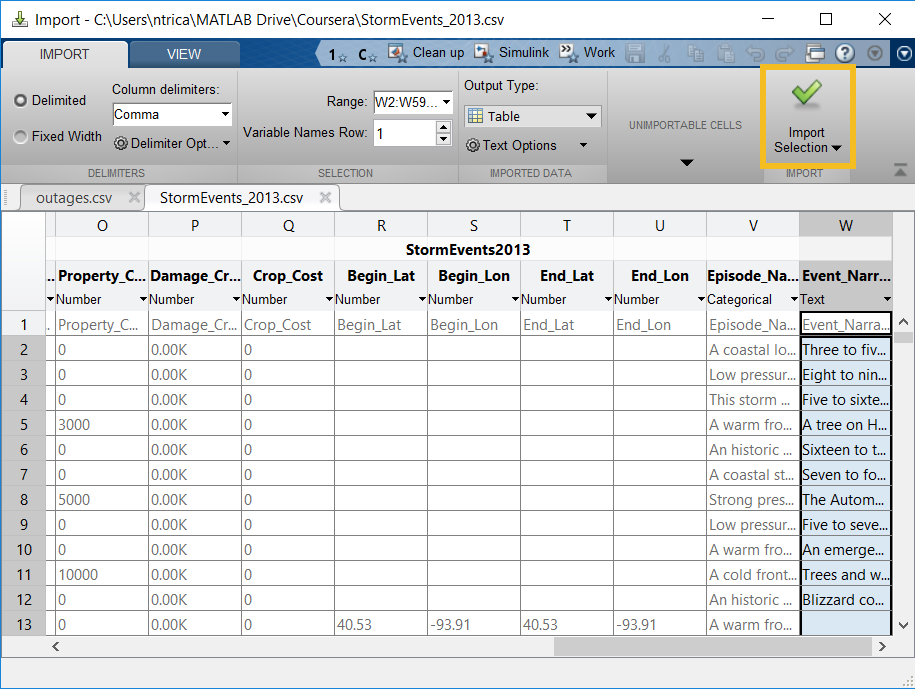

The table `StormEvents2013` should now be imported into your Workspace. The next line will only run if you successfully imported the data and did not change the name of the table.

StormEvents2013

StormEvents2013 = 59985×23 table
    EpisodeID     Event_ID         State        Year     Month         Event_Type          Begin_Date_Time      Timezone       End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                      

The variable `Event_Narrative` inside the table `StormEvents2013` stores text data. The data type in this case is `string`. You can see the data type by clicking in the table and using the drop down menu like shown in the picture below:

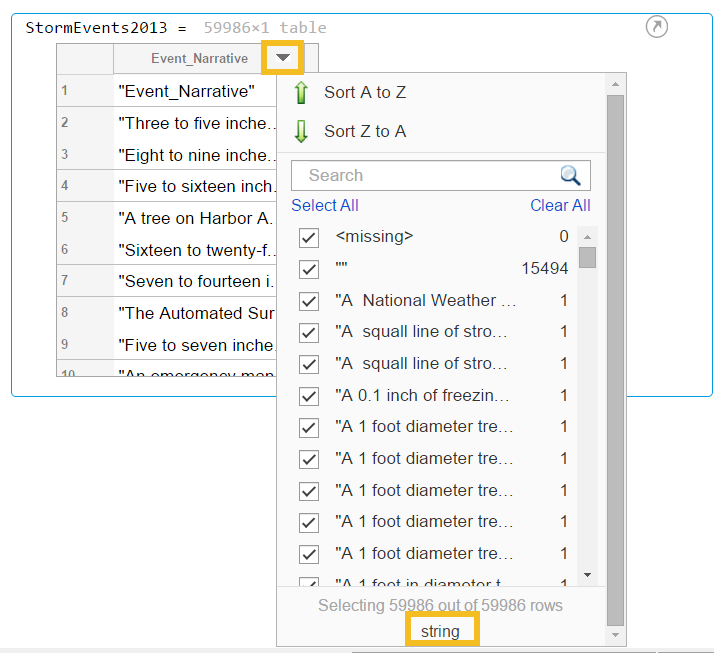

Note that every entry starts and ends with a double quote ("), which indicates the start and end of a string. For example:

exampleString = "Today's weather is awesome!"

exampleString = "Today's weather is awesome!"

Use square brackets to store more than one string in a variable:

exampleArray = ["green"; "red"; "blue"]

exampleArray = 3×1 string array
    "green"
    "red"
    "blue"


To access, use the same notation as before with numbers:

exampleArray(2)

ans = "red"

StormEvents2013.Event_Narrative(3)

ans = "Five to sixteen inches of snow fell across eastern Hillsborough County."

You can access the values just like elements of a vector. Also notice, that the strings don't need to have the same length. 

It is also possible to convert a variable to a string using the `string` function. Consider a variable `Value`:

Value = 7

Value = 7

When you check the data type of `Value` in the Workspace, you'll see that it is `double`. Now, create a string variable `Currency`:

Currency = "Euro"

Currency = "Euro"

When you want to save `Value` and `Currency` together, use the `string` function to convert `Value` to a string and combine both in one variable:

Price = string(Value) + " " + Currency

Price = "7 Euro"

The variable `Price` is a string now, which is also indicated by the double-quotes.

#### Char

You may encounter a single quote(') enclosing text when reviewing examples in the documentation or in code from other sources. Single quotes indicate that a variable is of data type `char`. This is an older data type and useful when you need to manipulate individual characters text (in most cases strings are easier to work with). This is an example:

exampleChar = 'It was raining cats and dogs.'

exampleChar = 'It was raining cats and dogs.'

To store more than one character array in a variable, use curly braces `{}`. These braces create another data type called `cell`. More recent code will typically use data of type `string` and `table`, but you will frequently run into code that uses `char` and `cell` data types. Continue to the section about cells to learn more. The last example in this live script will bring all of the data types together.

Use the `string `function to convert from `char` to `string`. 

myString = string(exampleChar)

myString = "It was raining cats and dogs."

### Dates and Times

Dates and Times are represented with a data type called `datetime`. Load the sample file `outages.csv`, containing data representing electric utility outages in the United States, which is included with MATLAB to explore examples of dates and times. The command `uiimport` opens the import tool with `outages.csv`. The folder that contains the file has been added to the MATLAB search path by default. If you want to import another dataset, navigate to the location first.

uiimport("outages.csv") 

What is the name for the table? Don't change the name. Otherwise the next lines of code will not work. Next, look at the data in the import tool and the automatically detected data types. The data set includes categoricals, datetimes, and double, contained in a table.

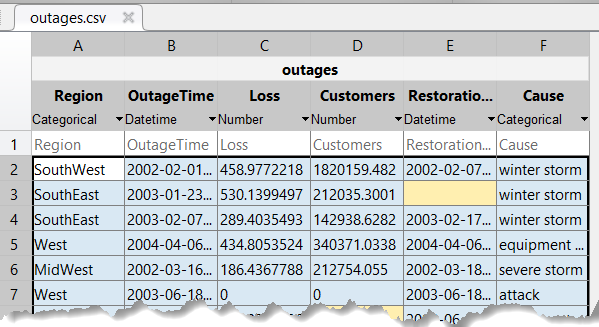

 Click on **Import Selection **and close the Import Tool.

The next code line calls the imported table `outages`, so you see it inside the live script:

outages

outages = 1468×7 table
     Region         OutageTime        Loss     Customers     RestorationTime          Cause         Year
    _________    ________________    ______    __________    ________________    _______________    ____

    SouthWest    2002-02-01 12:18    458.98    1.8202e+06    2002-02-07 16:50    winter storm       2002
    SouthEast    2003-01-23 00:49    530.14    2.1204e+05                 NaT    winter storm       2003
    SouthEast    2003-02-07 21:15     289.4    1.4294e+05    2003-02-17 08:14    winter storm       2003
    West         2004-04-06 05:44    434.81    3.4037e+05    2004-04-06 06:10    equipment fault    2004
    MidWest      2002-03-16 06:18    186.44    2.1275e+05    2002-03-18 23:23    severe storm       2002
   

Look at `OutageTime` in the output section. The data type for this variable is `datetime`. Execute the next line to extract a single entry:

outages.OutageTime(1)

ans = datetime
   2002-02-01 12:18


Here you see the year, month and day together with the hours and minutes. This marks a point in time for this particular observation in the table and all of this is stored in one value. 

You can extract information like year or month from a `datetime` variable. This is very useful for further analysis when your dataset does not already have columns for the year or month. The function `year` can be used like this:

outages.Year = year(outages.OutageTime)

outages = 1468×7 table
     Region         OutageTime        Loss     Customers     RestorationTime          Cause         Year
    _________    ________________    ______    __________    ________________    _______________    ____

    SouthWest    2002-02-01 12:18    458.98    1.8202e+06    2002-02-07 16:50    winter storm       2002
    SouthEast    2003-01-23 00:49    530.14    2.1204e+05                 NaT    winter storm       2003
    SouthEast    2003-02-07 21:15     289.4    1.4294e+05    2003-02-17 08:14    winter storm       2003
    West         2004-04-06 05:44    434.81    3.4037e+05    2004-04-06 06:10    equipment fault    2004
    MidWest      2002-03-16 06:18    186.44    2.1275e+05    2002-03-18 23:23    severe storm       2002
   

Here, you use the column `OutageTime` of the table `outages`, return only the year and assign it to a new variable. The result is saved as a new column variable of the `outages `table, called `Year`. It gets appended to the end of the existing table `outages`. To explore further, hover over the column called `Year`. Click on the arrow to open a drop down menu similar to the one pictured:

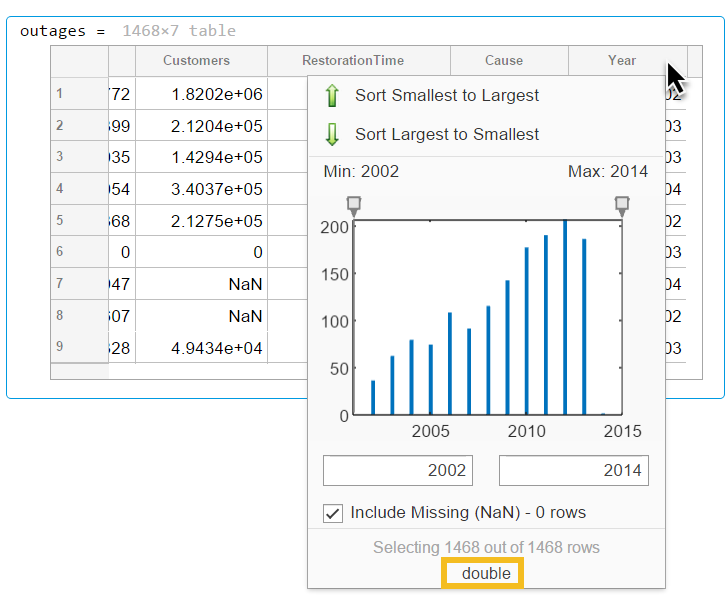

At the bottom you see the data type of your variable. In this case, `outages.Year` is of type double. Now, try it out yourself and append another column for the month. Also check the [documentation for the function month](https://www.mathworks.com/help/matlab/ref/datetime.month.html) to find out how to output the name for the month instead of the number.

% enter your code here
outages.Month = month(outages.OutageTime, 'name')

outages = 1468×8 table
     Region         OutageTime        Loss     Customers     RestorationTime          Cause         Year        Month    
    _________    ________________    ______    __________    ________________    _______________    ____    _____________

    SouthWest    2002-02-01 12:18    458.98    1.8202e+06    2002-02-07 16:50    winter storm       2002    {'February' }
    SouthEast    2003-01-23 00:49    530.14    2.1204e+05                 NaT    winter storm       2003    {'January'  }
    SouthEast    2003-02-07 21:15     289.4    1.4294e+05    2003-02-17 08:14    winter storm       2003    {'February' }
    West         2004-04-06 05:44    434.81    3.4037e+05    2004-04-06 06:10    equipment fau

### Categories

Examine the `Region` variable of the `outages` table. This variable stores 5 different values: MidWest, NorthEast, SouthEast, SouthWest, and West. Scroll through `outages.Region` and notice that all of these values get repeated for many times. The data type `categorical` is ideal for a finite set of repeated, discrete values. Unlike a `string` variable, a `categorical` value takes up less space due to the repeated values, and allows for operations involving grouping. Note, that categories or groups have meaningful names which make it easy to work with.

Consider this short example to create your own categorical variable. Start with a string vector and then convert it to a categorical.

myStringVec = ["blue"; "yellow"; "blue"; "blue"; "yellow"]

myStringVec = 5×1 string array
    "blue"
    "yellow"
    "blue"
    "blue"
    "yellow"


myCatVar = categorical(myStringVec)

myCatVar = 5×1 categorical array
     blue 
     yellow 
     blue 
     blue 
     yellow 


Categories can have a natural order, but it is not required. Read more in the documentation how to [Create an Ordinal Categorical Array](https://www.mathworks.com/help/matlab/matlab_prog/create-categorical-arrays.html#CreateCategoricalArraysExample-2).

Return to the example with the electricity outages. You can use categorical arrays like `Region` to select groups of rows. This way, you can look at only the outages reported in the West of the US. The following example uses logical indexing with a criteria that uses a categorical variable. 

outagesWest = outages(outages.Region=="West",:)

outagesWest = 354×8 table
    Region       OutageTime        Loss     Customers     RestorationTime          Cause         Year        Month    
    ______    ________________    ______    __________    ________________    _______________    ____    _____________

     West     2004-04-06 05:44    434.81    3.4037e+05    2004-04-06 06:10    equipment fault    2004    {'April'    }
     West     2003-06-18 02:49         0             0    2003-06-18 10:54    attack             2003    {'June'     }
     West     2004-06-20 14:39    231.29           NaN    2004-06-20 19:16    equipment fault    2004    {'June'     }
     West     2002-06-06 19:28    311.86           NaN    2002-06-07 00:51    equipment fault    2002    {

Look at the resulting table on the right. It contains only entries from the Region West. You could now start your analysis by exploring the data for different groups or even create your own categories and analyze further. You will learn how to do this later in this course.

## Heterogeneous Data

Review the Overview of the MATLAB Data Types picture from the beginning of this script. This section explores data types that act as containers for storing heterogeneous data. 

### Table

Earlier in this live script, you imported a CSV-file. In the Workspace this data was represented by a `table`. The next line displays the `table` in the output section:

outages

outages = 1468×8 table
     Region         OutageTime        Loss     Customers     RestorationTime          Cause         Year        Month    
    _________    ________________    ______    __________    ________________    _______________    ____    _____________

    SouthWest    2002-02-01 12:18    458.98    1.8202e+06    2002-02-07 16:50    winter storm       2002    {'February' }
    SouthEast    2003-01-23 00:49    530.14    2.1204e+05                 NaT    winter storm       2003    {'January'  }
    SouthEast    2003-02-07 21:15     289.4    1.4294e+05    2003-02-17 08:14    winter storm       2003    {'February' }
    West         2004-04-06 05:44    434.81    3.4037e+05    2004-04-06 06:10    equipment fau

A `table` stores column-oriented or tabular data, such as columns from a text file or spreadsheet. Each column represents a different variable in the `table` and can have a different data type and size as long as all variables have the same number of rows.

Depending on the data file, you could have separate variables in your workspace instead of a `table`. To create a `table` from these variables, use the `table` function. Go through the final example where everything comes together and try out yourself. 

Tables provide a convenient way to keep similar data together and labeled while still allowing access to individual rows and columns. You will work with tables throughout the whole specialization and see many examples to explore your table data.

### Cell

Another heterogeneous data type you might find in many examples in the documentation is `cell`. This is an older data type and one of the most commonly used containers for storing non-tabular, heterogenous data.

Same as with tables, `cell` stores data with different data types in one `cell` variable. Here are a few examples:

myCell1 = {7}

myCell1 = 1×1 cell array
    {[7]}


myCell2 = {'This is a first character array';'and this a second'}

myCell2 = 2×1 cell array
    {'This is a first character array'}
    {'and this a second'              }


myCell3 = {21, "Station 1"; 22, "Station 2"; 23, "Station 3"; 17, "Station 2"}

myCell3 = 4×2 cell array
    {[21]}    {["Station 1"]}
    {[22]}    {["Station 2"]}
    {[23]}    {["Station 3"]}
    {[17]}    {["Station 2"]}


Notice the curly braces `{}` that denote the creation of a `cell` array. To extract one element of a cell variable, you need to specify the row and column:

myCell3(2,2)

ans = 1×1 cell array
    {["Station 2"]}


The result is the container stored in the second row, and second column, and not the contents of that container. Use curly brackets again to extract the string:

myCell3{2,2}

ans = "Station 2"

Go through the final example to see how to work with data containing cells.

## Example - Bringing it all together

Throughout this live script you have created many variables, so clear your Workspace before you start. Call the `clear` command as follows: 

clear

Often data isn’t in the format we want. It can have missing values, extraneous entries, or a data type that does not allow for a calculation you want to perform. You will address these challenges later in this course and throughout the specialization. The best way to mitigate many of these problems is to address them as you import the data. When using the Import Tool, you will most likely have a good start, since it auto-detects the data type for you, but consider a case where your data is imported differently. Start with loading a dataset into the workspace. Use the `load` function with the file `patients.mat`. The file extension MAT identifies it as a MATLAB data file. This file is also included with MATLAB.

load('patients.mat') 

This command loads the following variables into the workspace:

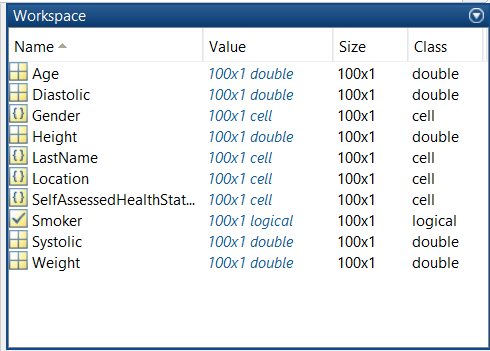

The dataset contains patient data with separate variables named `Age, Diastolic`, `Gender`, `Height`, `LastName`, `Location`, `SelfAssessedHealthStatus`, `Smoker`, `Systolic` and `Weight`. 

All variables have the same size but different data types. There are variables of type `double` that contain numbers, the `logical` variable `Smoker` describing if a patient is a smoker or not (true/false) and 4 `cell` variables `Gender`, `LastName`, `Location` and `SelfAssessedHealthStatus`. In this section you will combine these variables into a single table variable, enabling you to see data for a patient in a single row.

Start with `Gender:` Execute the next line to see what this variable looks like:

Gender

Gender = 100×1 cell array
    {'Male'  }
    {'Male'  }
    {'Female'}
    {'Female'}
    {'Female'}
    {'Female'}
    {'Female'}
    {'Male'  }
    {'Male'  }
    {'Female'}
    {'Female'}
    {'Female'}
    {'Male'  }
    {'Male'  }
    {'Female'}
    {'Male'  }
    {'Male'  }
    {'Female'}
    {'Male'  }
    {'Male'  }
    {'Female'}
    {'Female'}
    {'Female'}
    {'Female'}
    {'Female'}
    {'Male'  }
    {'Female'}
    {'Female'}
    {'Male'  }
    {'Male'  }


It is a cell array, where each cell contains text, either the word Male or Female.  

Because the variable contains a finite set of discrete variables, convert Gender to a `categorical` array.

Gender = categorical(Gender)

Gender = 100×1 categorical array
     Male 
     Male 
     Female 
     Female 
     Female 
     Female 
     Female 
     Male 
     Male 
     Female 
     Female 
     Female 
     Male 
     Male 
     Female 
     Male 
     Male 
     Female 
     Male 
     Male 
     Female 
     Female 
     Female 
     Female 
     Female 
     Male 
     Female 
     Female 
     Male 
     Male 


Now, look at `LastName`:

LastName

LastName = 100×1 cell array
    {'Smith'    }
    {'Johnson'  }
    {'Williams' }
    {'Jones'    }
    {'Brown'    }
    {'Davis'    }
    {'Miller'   }
    {'Wilson'   }
    {'Moore'    }
    {'Taylor'   }
    {'Anderson' }
    {'Thomas'   }
    {'Jackson'  }
    {'White'    }
    {'Harris'   }
    {'Martin'   }
    {'Thompson' }
    {'Garcia'   }
    {'Martinez' }
    {'Robinson' }
    {'Clark'    }
    {'Rodriguez'}
    {'Lewis'    }
    {'Lee'      }
    {'Walker'   }
    {'Hall'     }
    {'Allen'    }
    {'Young'    }
    {'Hernandez'}
    {'King'     }


It is a `cell` array of character arrays. You can convert this `cell` array to a string.

LastName = string(LastName)

LastName = 100×1 string array
    "Smith"
    "Johnson"
    "Williams"
    "Jones"
    "Brown"
    "Davis"
    "Miller"
    "Wilson"
    "Moore"
    "Taylor"
    "Anderson"
    "Thomas"
    "Jackson"
    "White"
    "Harris"
    "Martin"
    "Thompson"
    "Garcia"
    "Martinez"
    "Robinson"
    "Clark"
    "Rodriguez"
    "Lewis"
    "Lee"
    "Walker"
    "Hall"
    "Allen"
    "Young"
    "Hernandez"
    "King"


The same applies to the variable `Location` and `SelfAssessedHealthStatus`: 

Location

Location = 100×1 cell array
    {'County General Hospital'  }
    {'VA Hospital'              }
    {'St. Mary's Medical Center'}
    {'VA Hospital'              }
    {'County General Hospital'  }
    {'St. Mary's Medical Center'}
    {'VA Hospital'              }
    {'VA Hospital'              }
    {'St. Mary's Medical Center'}
    {'County General Hospital'  }
    {'County General Hospital'  }
    {'St. Mary's Medical Center'}
    {'VA Hospital'              }
    {'VA Hospital'              }
    {'St. Mary's Medical Center'}
    {'VA Hospital'              }
    {'St. Mary's Medical Center'}
    {'VA Hospital'              }
    {'County General Hospital'  }
    {'County General Hospital'  }
    {'VA Hospital'              }
    {'VA Hospital'              }
    {'VA Hospital'              }
    {'County General Hospital'  }
    {'County General Hospital'  }
    {'VA Hospital'              }
    {'VA Hospital'              }
    {'County General Hospital'  }
    {'County General

Location = string(Location)

Location = 100×1 string array
    "County General Hospital"
    "VA Hospital"
    "St. Mary's Medical Center"
    "VA Hospital"
    "County General Hospital"
    "St. Mary's Medical Center"
    "VA Hospital"
    "VA Hospital"
    "St. Mary's Medical Center"
    "County General Hospital"
    "County General Hospital"
    "St. Mary's Medical Center"
    "VA Hospital"
    "VA Hospital"
    "St. Mary's Medical Center"
    "VA Hospital"
    "St. Mary's Medical Center"
    "VA Hospital"
    "County General Hospital"
    "County General Hospital"
    "VA Hospital"
    "VA Hospital"
    "VA Hospital"
    "County General Hospital"
    "County General Hospital"
    "VA Hospital"
    "VA Hospital"
    "County General Hospital"
    "County General Hospital"
    "County General Hospital"


SelfAssessedHealthStatus

SelfAssessedHealthStatus = 100×1 cell array
    {'Excellent'}
    {'Fair'     }
    {'Good'     }
    {'Fair'     }
    {'Good'     }
    {'Good'     }
    {'Good'     }
    {'Good'     }
    {'Excellent'}
    {'Excellent'}
    {'Excellent'}
    {'Poor'     }
    {'Poor'     }
    {'Excellent'}
    {'Good'     }
    {'Good'     }
    {'Excellent'}
    {'Fair'     }
    {'Good'     }
    {'Good'     }
    {'Excellent'}
    {'Fair'     }
    {'Fair'     }
    {'Fair'     }
    {'Good'     }
    {'Poor'     }
    {'Excellent'}
    {'Good'     }
    {'Poor'     }
    {'Excellent'}


SelfAssessedHealthStatus = string(SelfAssessedHealthStatus)

SelfAssessedHealthStatus = 100×1 string array
    "Excellent"
    "Fair"
    "Good"
    "Fair"
    "Good"
    "Good"
    "Good"
    "Good"
    "Excellent"
    "Excellent"
    "Excellent"
    "Poor"
    "Poor"
    "Excellent"
    "Good"
    "Good"
    "Excellent"
    "Fair"
    "Good"
    "Good"
    "Excellent"
    "Fair"
    "Fair"
    "Fair"
    "Good"
    "Poor"
    "Excellent"
    "Good"
    "Poor"
    "Excellent"


Your Workspace should now look similar to the following image:

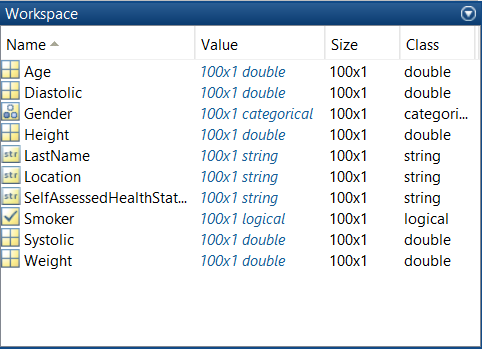

All variables belong to the same dataset and store the same number of observations. This qualifies for combining them as a `table`. Use the `table` function to create this table:

PatientData = table(LastName, Age, Gender, Weight, Diastolic, Systolic, Smoker, Location, SelfAssessedHealthStatus)

PatientData = 100×9 table
     LastName     Age    Gender    Weight    Diastolic    Systolic    Smoker             Location              SelfAssessedHealthStatus
    __________    ___    ______    ______    _________    ________    ______    ___________________________    ________________________

    "Smith"       38     Male       176         93          124       true      "County General Hospital"            "Excellent"       
    "Johnson"     43     Male       163         77          109       false     "VA Hospital"                        "Fair"            
    "Williams"    38     Female     131         83          125       false     "St. Mary's Medical Center"          "Good"

The resulting table has 9 columns, representing the previously separate variables. Scroll through the table in the output section to see your created table. You could also create a smaller table only containing the variables you need. 